# **demo20 of Im2mesh package**

demo20 - Create tetrahedral mesh based on 3d voxel image

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

In Im2mesh package, the workflow of creating tetrahedral mesh is the same as the workflow in JM Hestroffer's XtalMesh ToolKit (see link below). The mesh generator of XtalMesh is fTetWild, which has very high meshing success rate due to its envelope-based meshing algorithm. Note that XtalMesh uses Python and cannot use 3d voxel image as input.

XtalMesh Github: [https://github.com/jonathanhestroffer/XtalMesh](https://github.com/jonathanhestroffer/XtalMesh)

XtalMesh paper: [https://doi.org/10.1007/s40192-022-00251-w](https://doi.org/10.1007/s40192-022-00251-w)

fTetWild Github: [https://github.com/wildmeshing/fTetWild](https://github.com/wildmeshing/fTetWild)

fTetWild paper: [https://dl.acm.org/doi/10.1145/3386569.3392385](https://dl.acm.org/doi/10.1145/3386569.3392385)

fTetWild video: [https://www.youtube.com/watch?v=RweR25IBeB8](https://www.youtube.com/watch?v=RweR25IBeB8)

I spent several days to rewrite the XtalMesh's code to make it work for MATLAB and 3d voxel image. In this demo, we also use fTetWild as mesh generator.

## Dependencies

To run demo20, we need to install fTetWild. 

No need to install any MATLAB toolboxes.

## Installation of fTetWild via Docker

1. Download and install [Docker Desktop](https://www.docker.com/products/docker-desktop/).

2. Run Docker. If you have trouble in running Docker, you can ask Gemini for help. In my persional windows PC, I need to enable virtualization in BIOS to run Docker.

3. Open your command-line shell, such as Windows PowerShell.

4. Type the following code within command-line shell to install my Docker image of fTetWild (1.7 GB).

    docker pull mjx0799/my_ftetwild_image

5. The installation may take a while (15-30 mins). After installation, your should be able to see the installed image in your Docker Desktop application.

## Setup

Before we start, open Docker Desktop application. Let it run in the background.

Open MATLAB, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

Clear variables.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Define a subfolder for saving mesh data.

% Define the name of subfolder
folderName = 'myMesh';
myMeshFolder = fullfile(pwd, folderName);

% Creates the folder if it doesn't exist
if ~exist(myMeshFolder, 'dir')
    mkdir(myMeshFolder); 
    disp('Folder created!');
end

Folder created!


## STEP 1. Import 3d voxel image

We can import 3d image using function importImSeqs or function importImStack. We have demostrated these two functions in the beginning of demo19.

imageFoloder = 'test_image_sequences';
im = importImSeqs( imageFoloder );

Use function plotVolFaces to plot faces. 

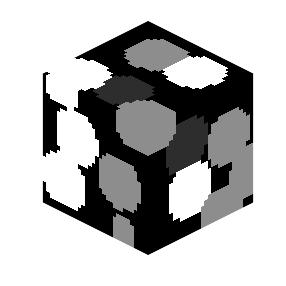

plotVolFaces( im );

We can use the function 'unique' to list all the grayscale intensity in the image.

unique(im)'

ans = 1×4 uint8 row vector
     0    61   134   239


We can check the totoal number of grayscale intensity in the image.

length(unique(im))

ans = 4

We identifies different phases in a image by their grayscales. Different grayscales correspond to different phases. If we have 4 level of grayscales in a image, the resulted meshes will contain 4 phases. 

## STEP 2. Convert to triangular surface mesh

We need to define the voxel spacing in the 3d voxel image. In the X-ray CT image of materials, the z spacing is usually different from the x and y spacing. We will set the actual phyiscal dimension of a voxel in STEP 10.

% Define the voxel spacing (default is 1x1x1)
voxelSpacing = [1.0, 1.0, 1.0];

We can convert 3d voxel image to triangular surface mesh.

% Extract triangular surface mesh
[nodes, triangles, phaseIDs] = extractPhaseMesh(im, voxelSpacing);

% Convert surface mesh to the output format of Dream.3D
[V, F, ntype, flabel] = convert2dream3d(nodes, triangles, phaseIDs);

## STEP 3. Smooth surface mesh

We will use constraint Taubin smoothing to smooth the 'blocky' triangular surface mesh. You can change 'num_iters' to tune surface smoothness. We can obtain smoother surface with a higher 'num_iters'. The typical value of 'num_iters' is 20-60.

num_iters = 100;
lamda = 0.5;
mu = -0.53;

The smoothing process may take some time. Wait until "Smoothing Done!" show up. 

Note that [JM Hestroffer's XtalMesh](https://github.com/jonathanhestroffer/XtalMesh) used Laplacian smoothing, but I prefer Taubin smoothing (without volume shrinkage).You can check Figure 3 in [JM Hestroffer's paper](https://doi.org/10.1007/s40192-022-00251-w) about the smoothing process.

disp('//////////////// Smoothing ////////////////');

//////////////// Smoothing ////////////////



% Geometric constraints
minX = min(V(:,1)); maxX = max(V(:,1));
minY = min(V(:,2)); maxY = max(V(:,2));
minZ = min(V(:,3)); maxZ = max(V(:,3));
geom = [double(V(:,1) > minX & V(:,1) < maxX), ...
        double(V(:,2) > minY & V(:,2) < maxY), ...
        double(V(:,3) > minZ & V(:,3) < maxZ)];  % N x 3

% Smoothing passes
% fprintf('Smooth Exterior Triple Lines\n');
V = graph_smooth_taubin(V, F, 'ext_triple', ntype, geom, lamda, mu, num_iters);

% fprintf('Smooth Interior Triple Lines\n');
V = graph_smooth_taubin(V, F, 'int_triple', ntype, geom, lamda, mu, num_iters);

% fprintf('Smooth Boundaries\n');
V = graph_smooth_taubin(V, F, 'bound', ntype, geom, lamda, mu, num_iters);

disp('//////////////// Smoothing Done! ////////////////');

//////////////// Smoothing Done! ////////////////


## STEP 4. Select phases (optional)

The input 3d voxel image usually has multiple phases. Different grayscales in the image correspond to different phases.

grayscale = unique(im)'

grayscale = 1×4 uint8 row vector
     0    61   134   239


We can use the following function the select the phases we desire. If we don't need to select phases, we can delete STEP 4 or set  grayscale_we_like=[];

grayscale_we_like = [ 0, 134, 239 ];
[V, F, flabel] = selectPhase( V, F, flabel, grayscale_we_like );

## STEP 5. Save surfaces as OFF file

Extract surfaces for each phase. We will use them later.

% Get surface mesh for each phase
phaseFaces = extractPhaseFaces(F, flabel);

We use function writeOFF to save surfaces as OFF file.

offFileName = 'surface.off'; 
offFilePath = fullfile(myMeshFolder, offFileName);

writeOFF(offFilePath, V, F);

//////////////// writeOFF Done! ////////////////


We can save these variables to mat file for backup.

save( 'surf.mat', 'V', 'F', 'phaseFaces' );

## STEP 6. Visualize surface mesh

We use function plotSurface to visualize surface mesh. Function plotSurface is much faster when running via m file script than mlx file.

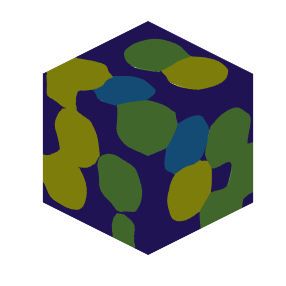

color_code = 2;
opt = [];   % reset
opt.faceAlpha = 1;
opt.sampleRatio = 1;

plotSurface( V, phaseFaces, color_code, opt );

If the input 3d image is large, function plotSurface could be very slow. I usually down-sample the surface to make the rendering faster. Down-sampling is achieved by setting 'opt.sampleRatio'.

'opt.sampleRatio = 1' means no down-sampling.

'opt.sampleRatio = 0.1' means roundly 10% down-sampling before plotting surface.

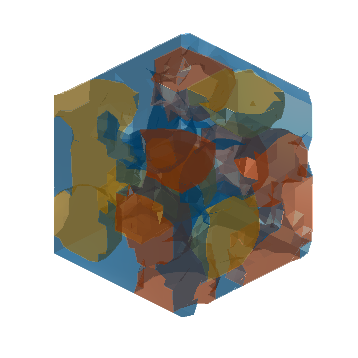

color_code = 1;
opt = [];   % reset
opt.faceAlpha = 0.5;
opt.sampleRatio = 0.1;
plotSurface( V, phaseFaces, color_code, opt );

## STEP 7. Generate tetrahedral mesh via fTetWild

To generate mesh via [fTetWild](https://github.com/wildmeshing/fTetWild), we need to construct a command and send the command to fTetWild via Docker.

There are two major parameters for fTetWild: Ideal edge length, Envelope of size epsilon.  You can check Figure 5 in [JM Hestroffer's paper](https://doi.org/10.1007/s40192-022-00251-w) about the effect of these two parameters. 

Using smaller ideal edge length gives a denser mesh but also takes longer time. 

Using smaller envelope preserves features better but also takes longer time.

According to fTetWild, we can use the following command line to set these two parameters. For other command lines, see fTetWild's github. 

`  -a,--la               Ideal edge length not scaled by diag_of_bbox. Excludes: --lr. (double, optional)`

`  -l,--lr               ideal_edge_length = diag_of_bbox * L. Excludes: --la. (double, optional, default: 0.05)`

`  -e,--epsr             epsilon = diag_of_bbox * EPS. (double, optional, default: 1e-3)`

Here is an example. The input is .off file. The output is .msh file (Gmsh format). You may ask Gemini to construct a Docker command.

idealEdgeLength = '5e-2';   % Ideal edge length
epsilon = '1e-3';           % Envelope of size epsilon

mshFileName = 'tet.msh';

% Construct the Docker Command
dockerCmd = [
    'docker run --rm -v "', myMeshFolder, ':/data" -w /data mjx0799/my_ftetwild_image ' ...
    '/fTetWild/build/FloatTetwild_bin ' ...
    '--input ', offFileName, ' ' ...
    '--output ', mshFileName, ' ' ...
    '--use-floodfill ' ...
    '--manifold-surface ' ...
    '--no-color ' ...
    '--no-binary ' ...
    '-l ', idealEdgeLength, ' ' ...
    '-e ', epsilon ...
    ];

We send the command to fTetWild via Docker. The mesh generation process could take a while (5-180 mins depending on input). Wait until "fTetWild Done!" show up. A .msh file (Gmsh) will be generated in the subfolder we created before.

disp('//////////////// fTetWild via Docker ////////////////');

//////////////// fTetWild via Docker ////////////////



% Start the timer
tic;

% Execute with '-echo' to see the real-time console output
[status, cmdout] = system(dockerCmd, '-echo');

6 10 12 2 9 5 16 13 0 14 4 1 19 8 18 11 3 17 15 7 
TBB threads 4
bbox_diag_length = 51.9615
ideal_edge_length = 2.59808
stage = 2
eps_input = 0.0519615
eps = 0.0287654
eps_simplification = 0.0230123
eps_coplanar = 5.19615e-05
dd = 0.034641
dd_simplification = 0.0277128
collapsing 2.58429
swapping 0.458511
#boundary_e1 = 4
#boundary_e2 = 5
#boundary_e1 = 4
#boundary_e2 = 5
known_surface_fs.size = 0
known_not_surface_fs.size = 0
initializing...
edge collapsing...
fixed 0 tangled element
success(env) = 6639
success = 9108(95433)
success(env) = 198
success = 258(60711)
success(env) = 8
success = 10(11744)
success(env) = 0
success = 0(384)
edge collapsing done!
time = 1.79319s
#v = 9120
#t = 53698
max_energy = 1716.8
avg_energy = 7.94542
//////////////// pass 0 ////////////////
edge splitting...
fixed 0 tangled element
success = 12570(12570)
edge splitting done!
time = 0.104611s
#v = 21690
#t = 118965
max_energy = 1716.8
avg_energy = 7.19381
edge collapsing...
fixed 0 tangled element
succes


% Stop the timer and store elapsed time
executionTime = toc;

% Check if it was successful
if status == 0
    disp('//////////////// fTetWild Done! ////////////////');
    fprintf('//////////////// Time = %.2fs ////////////////\n', executionTime);
else
    disp('//////////////// Error occurred ////////////////');
end

//////////////// fTetWild Done! ////////////////


//////////////// Time = 53.39s ////////////////


## STEP 8. Import .msh file & assign phase labels

We use function readMsh to import the .msh file into MATLAB.

mshFilePath = fullfile( myMeshFolder, mshFileName );

[vert, ele] = readMsh( mshFilePath ); 

Loaded 18948 nodes and 101233 elements.


We use function label_tetrahedrons to assign phase labels.

tnum = label_tetrahedrons(vert, ele, phaseFaces, V);

//////////////// Phase labeling ////////////////
Phase 1 / 4 ...
Phase 2 / 4 ...
Phase 3 / 4 ...
Phase 4 / 4 ...
//////////////// Labeling complete! ////////////////



% Remove background tetrahedrons
idx = (tnum == 0);
ele(idx, :) = [];
tnum(idx) = [];

We got 3 variables: vert, ele, tnum

**vert**: Mesh nodes. It’s a Nn-by-3 matrix, where Nn is the number of nodes in the mesh. Each row of vert contains the x, y, z coordinates for that mesh node.

**ele**: Mesh elements. Each row in ele contains the indices of the nodes for that mesh element.

**tnum**: Label of phase. Ne-by-1 array, where Ne is the number of elements.

  tnum(j,1) = k; means the j-th element belongs to the k-th phase.

We use function tetcost to check mesh quality. The computation method in function tetcost is the same as MATLAB built-in function [meshQuality](https://www.mathworks.com/help/pde/ug/pde.femesh.meshquality.html).

tetcost(vert, ele);


--- Tetrahedral Mesh Quality Summary ---
Total Elements:      101233
Mean Quality (Q):    0.8084
Min Quality (Q):     0.2763
Max Quality (Q):     0.9986
Poor Elements (<0.1): 0
----------------------------------------



Plot mesh quality.

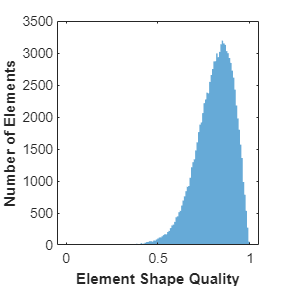

Q = tetcost(vert, ele);

figure
histogram(Q, 'BinLimits', [0,1], 'EdgeColor', 'none')
xlabel( "Element Shape Quality", "fontweight", "b" )
ylabel( "Number of Elements", "fontweight", "b" )

save('tet.mat', 'vert', 'ele', 'tnum');

## STEP 9. Visualize tetrahedral mesh

We use function plotMesh3d to plot mesh.

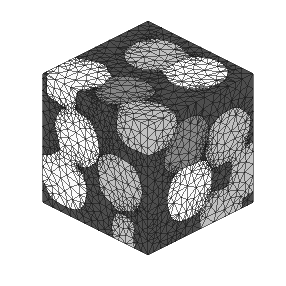

color_code = 0;
opt = []; % reset
opt.faceAlpha = 1;
opt.edgeAlpha = 0.6;

plotMesh3d(vert, ele, tnum, color_code, opt);

Other settings.

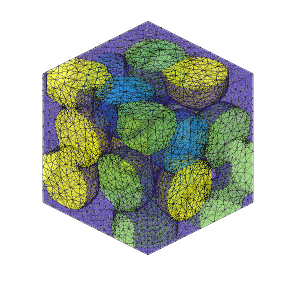

color_code = 2;
opt = []; % reset
opt.faceAlpha = 0.5;
opt.edgeAlpha = 0.3;

plotMesh3d( vert, ele, tnum, color_code, opt );

Define cutting plane to check interior. You can ask Gemini to define more setting.

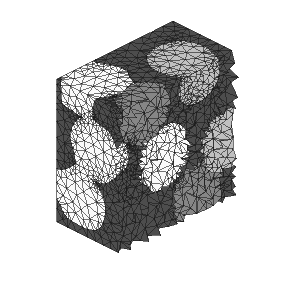

opt = []; % reset
opt.cutPlaneYZ = 15.5;    % plot elements where x <= 15
opt.faceAlpha = 1;
opt.edgeAlpha = 0.6;

plotMesh3d(vert, ele, tnum, 0, opt);

[ vert, ele, tnum, vert2, ele2 ] = voxelMesh( im );

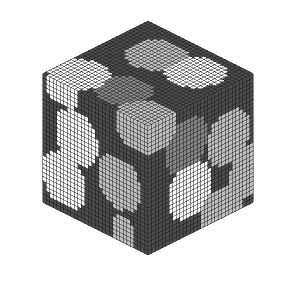

plotMesh3d( vert, ele, tnum )

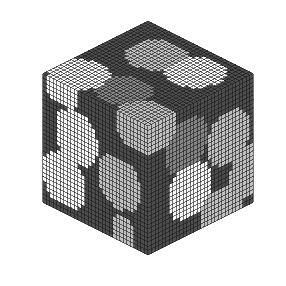

opt = []; % reset
opt.faceAlpha = 1;
opt.edgeAlpha = 0.6;
plotMesh3d( vert, ele, tnum,  0, opt)

We can plot the mesh for one of the phases. For example, the 2nd phase.

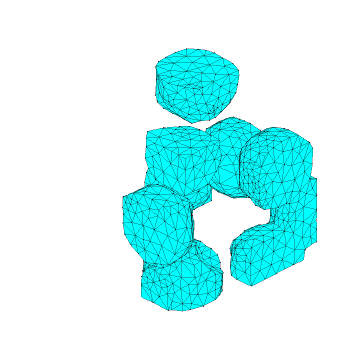

index = 2;

ele_temp = ele( tnum == index, : );
[ vert_temp, ele_temp ] = delRedundantVertex( vert, ele_temp );

color_code = 4;
opt = []; % reset
opt.faceAlpha = 1;
opt.edgeAlpha = 0.3;
plotMesh3d( vert_temp, ele_temp, [], color_code, opt );

## STEP 10. Export mesh as inp or bdf file

Set up scale.

% physical dimensions of a voxel in the image
dx = 1;

Scale node coordinates according to dx.

% scale node coordinates of linear elements
vert = vert * dx;

### Export mesh as bdf file (Nastran bulk data)

precision = 8;
file_name = 'test_3d.bdf';

printBdf3d( vert, ele, tnum, [], precision, file_name );

printBdf3d Done! Check the bdf file!


### Export mesh as inp file (Abaqus)

Please refer to the following link to learn more about exporting mesh: [https://github.com/mjx888/writeMesh/blob/main/README.md](https://github.com/mjx888/writeMesh/blob/main/README.md)

**Linear element**

ele_type = 'C3D4';
precision = 8;
file_name = 'test_linear.inp';

opt = [];
opt.tf_printMaxMinNode = 0;
opt.tf_printInterfNode = 0;

printInp3d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp3d Done! Check the inp file!


**Quadratic element**

We use function insertNode to convert the linear elements to quadratic elements.

% vert2, ele2 define quadratic elements
[vert2, ele2] = insertNode3d(vert, ele);

Export

ele_type = 'C3D10';
precision = 8;
file_name = 'test_quadratic.inp';

opt = [];
opt.tf_printMaxMinNode = 0;
opt.tf_printInterfNode = 0;

printInp3d( vert2, ele2, tnum, ele_type, precision, file_name, opt );

printInp3d Done! Check the inp file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo